# LIDAR Functions

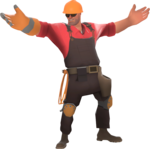

Eliyahu Suskind and Mahdi, 3/6/2023, Revision 1

clc       % clear command window
clear     % clear MATLAB workspace

### Set Up Control System

% Set-up arduino
[robotArduino, blinkLED] = SETUPARDUINO('COM13');

% Turn board LED on and off to signal program has started
blink(robotArduino, blinkLED, 5);
disp('Warning! Data Collection Active!')



r = rateControl(0.1);   % create a 0.1 hz loop rate
reset(r);               % reset loop to time zero

### Run Control Loop

controlFlag = 1;                     
while (controlFlag < nTests + 1)

end


### Mission data processing

### Clean and Shutdown

End program by clearing arduino object and command window

clc
disp('Arduino program has ended');
clear robotArduino
beep

### Robot Functions

function [robotArduino, blinkLED] = SETUPARDUINO(COMPORT)
% Purpose: configure and create a global arduino object
% Input: COMPORT is COM port of arduino as string
% Output: arduinoCont is arduino obj, myServo is servo obj, LED is LED pin
    
% create global arduino obj
robotArduino = arduino(COMPORT, 'Uno', 'Libraries', 'Servo');

% configure pin 13 for indicator LED
blinkLED = 'D13';
configurePin(robotArduino, blinkLED, 'DigitalOutput');


end

function [] = blink(a, LED, n)
% Purpose: blink indicator LED
% Inputs: a is arduino obj, LED is LED pin, n is number of blinks as int

    for bIndex = 1:n
        writeDigitalPin(a, LED, 0);
        pause(0.2);
        writeDigitalPin(a, LED, 1);
        pause(0.2);
    end

end

### Sense Functions

function [] = SENSE()
% Purpose:
% Input: 
% Output: 
    
end